# Práctica 4. Sistemas basados en eventos discretos

## Identificación del alumno

Nombre: Ana

Apellidos: Robledano Abasolo

Grupo:  B

DNI:  51504162D                               Problema nº:   1

## Instrucciones

- Tiene el tiempo de clase para realizar la práctica

- Rellena tu identificación. No rellenar correctamente la identificación restará 1.0 puntos en la calificación final.

- Identifica el/los problemas a resolver. No borres el resultado.

- Rellena el/los números de los dos problemas en el lugar adecuado de tu identificación.

- Nombra el archivo de la forma indicada. Nombrarlo mal resta 0.5 puntos a la calificación final.

- Lee la rúbrica para conocer cómo se va a corregir la práctica.

- Cuando tengas la seguridad de saber lo que se te va a pedir y cómo se te va a calificar, continúa en el punto siguiente.

- Resuelve el problema. No cometas faltas de ortografía. Las confusiones debidas al uso del teclado no se considerarán como tales. No metas paja: no puntúa.

- Vuelve a leer todas las instrucciones. Comprueba que todo es correcto.

- Repasa la práctica. Corrige lo que sea necesario. Incluyendo faltas de ortografía o de escritura.

- Sube el archivo al lugar habilitado para ello en el Canvas.

## Identificar el problema a resolver

NO MODIFIQUE NADA DEL SIGUIENTE CÓDIGO

**Corra el programa siguiente e introduce tu DNI ****cuando te lo pida****:**

clear, clc
DNIt = inputdlg('INTRODUCIR EL DNI SIN LETRA NI PUNTOS');
if isempty(cell2mat(DNIt))
    errordlg('No puede dejar el DNI vacío', 'Error en la entrada')
    return
end
rng(str2num(cell2mat(DNIt)))
prob1 = ceil(3*rand);

fprintf(1,'DNI = %s \n', cell2mat(DNIt))

DNI = 51504162 


fprintf(1,'Tiene que resolver el problema: \n') 

Tiene que resolver el problema: 


fprintf(1,'     Problema %1.0f  \n', prob1)

     Problema 1  


Instrucciones

## Entrega

Nombra el archivo como: **P04Apellido1Apellido2Nombre.zip** que contenga este fichero (con su nombre) y todos aquellos ficheros auxiliares que necesita para completar la práctica, incluidos los modelos de Simulink. Súbelo al enlace de la tarea. Nombrar mal el archivo restará 0.5 puntos en la calificación final.

Instrucciones

## Rúbrica

El problema vale 9 puntos, distribuidos de la siguiente manera:

a) Introducción donde se expongan las diversas soluciones y suposiciones que el alumno considere pertinentes. (1p)

b) Esquema del modelo o modelos propuestos (2p)

c) Gráficos de salida con los resultados (1p)

d) Respuesta a las preguntas planteadas (4p)

e) Conclusiones (1p)

1 punto adicional por la limpieza, el orden y la claridad de las exposiciones y figuras.

## Problema 1				

Queremos montar un negocio de reparación de máquinas de jardinería. Lógicamente, hay muchos tipos de máquinas y se quiere probar la forma más eficiente de repararlas.

La primera forma de organizar la producción es reparar bajo pedido, esto es, se repara aquella máquina que previamente se ha entregado alguna de las tiendas, y por tanto, se mezclarán en la reparación distintos tipos de máquina. Por ello, la llegada a la línea de producción será una distribución de Poisson de media 2. Como son máquinas distintas, sus tiempos de reparación son distintos (existen 5 tipos de máquinas a reparar). No sabemos qué tipo de máquina puede llegar en cada momento. Los tiempos de reparación siguen una distribución de Poisson de media 1, 2, 3, 4 y 5 respectivamente.

La segunda forma de organizar la reparación es más homogénea: existe una línea de reparación por cada tipo de máquina, cada una de ellas con las mismas tasas de llegada y los mismos tiempos de reparación que la formulación anterior.

Con esta información, se desea saber qué tipo de línea de reparación es más eficiente en un periodo de tiempo dado y cuántas máquinas salen reparadas en cada una de las configuraciones al final del periodo. Incluya las gráficas que sean necesarias para poder comparar ambas configuraciones. En especial, se desea saber en todo momento las entidades que se encuentran en cola en cada una de las configuraciones. ¿Cuál sería el tiempo medio de reparación en cada una de las configuraciones?

Si necesita hacer suposiciones, indíquelas claramente siempre y cuando no simplifiquen el problema.

### Solución	

### MODELO 1

Los clientes entran a la tienda según una distribución de Poisson de media 2, una vez allí, se disponen en una cola FIFO (ya que el que llega el primero es atendido antes) y son dirigidos a un servidor de reparación donde no hay ninguna restricción sobre el tipo de máquina que llegue. En el servidor se repara cualquiera de los 5 tipos de máquinas. Aunque dependiendo del tipo, el tiempo de reparación varía.

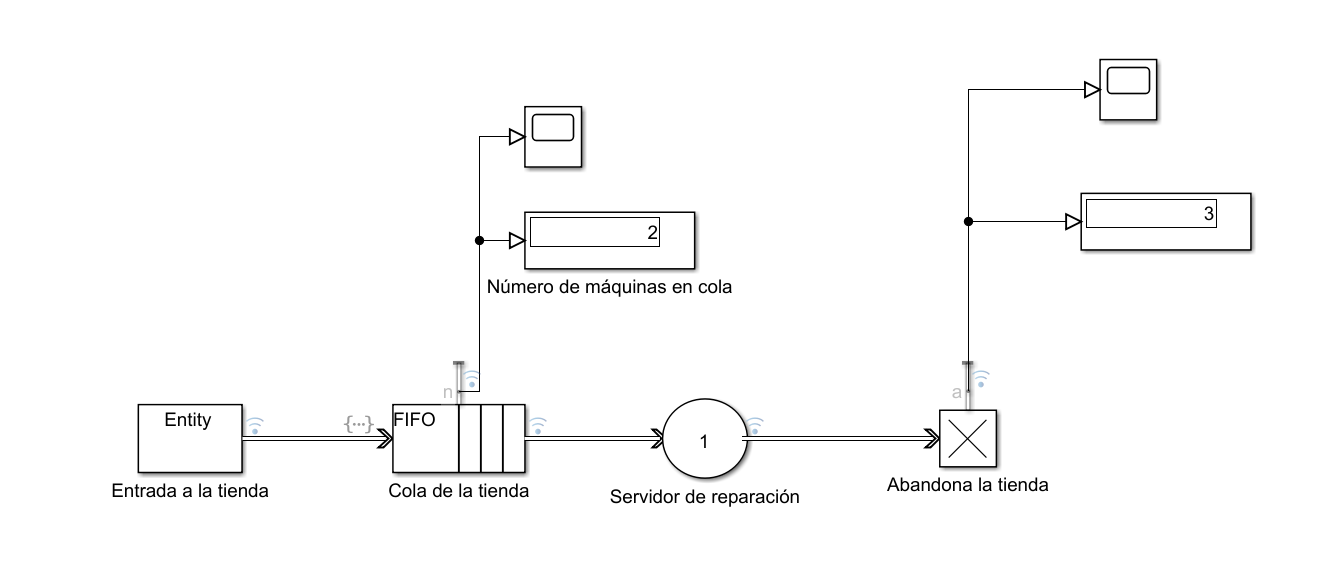

**Explicación del modelo 1:**

- ENTITY GENERATOR: representa la entrada de los clientes a la tienda. Se especifica en el tipo de generación de entidades mediante MATLAB source, una llegada según una distribución de poisson de media 2 (`dt = poissrand(2)). `También se modifica el atributo por defecto a `MaquinaTipo` con valor inicial 1.

- ENTITY QUEUE: es la cola de la tienda del tipo FIFO (como suelen ser las colas en cualquier comercio) y capacidad 10, ya que la reparación de máquinas es costoso y requiere tiempo. El atributo se modifica, de manera aleatoria entre valores del 1 al 5 para cada tipo: `entity.MaquinaTipo = randi([1,5]);`

- ENTITY SERVER: es el taller o servidor de reparación donde se arreglan las máquinas, las máquinas llegan al taller sin ninguna restricción, ya que en el taller se repara cualquier tipo de máquinas. No obstante, dependiendo del tipo de máquina el tiempo de reparación varía. $\mathrm{dt}=\mathrm{poissrnd}\left(\mathrm{entity}\ldotp \mathrm{MaquinaTipo}\right);$ y una capacidad de 1, ya que cada máquina requiere todo el personal del taller para ser reparada.

- ENTITY TERMINATOR: la salida de la máquina de la tienda tras ser reparada.

**Gráficas del modelo 1:**

Inicialmente, se generan unas entidades, en el tiempo según una distribución de Poisson de media 2, como vemos en la gráfica:

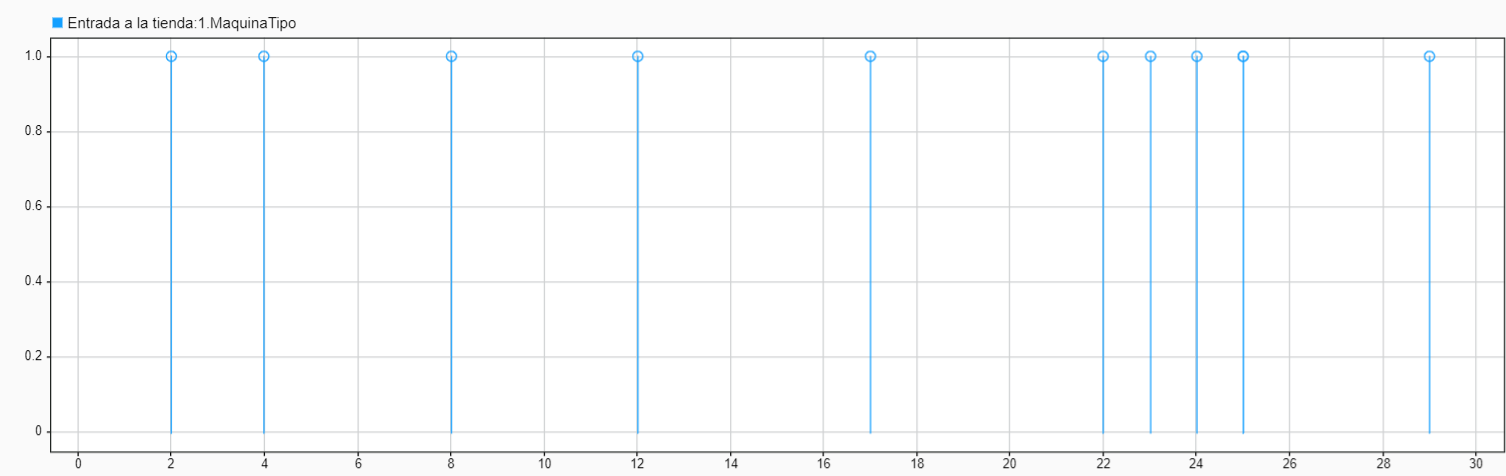

El tipo de la máquina se inicializa en 1 pero luego lo cambiaremos para que cada máquina pueda ser de manera aleatoria de un tipo entre 1 y 5. (Esto lo hacemos porque al llegar a la tienda, no sabemos que tipo de máquina el cliente desea reparar).

Una vez en la cola de la tienda observamos el tipo de máquina que hay en ella en cada momento. Por ejemplo, en el tiempo 2, ya que la primera entidad según la gráfica anterior se genera en ese tiempo`,`hay en la cola una máquina del tipo 5. Y en el tiempo 29, hay 3 máquinas en cola, una del tipo 1, otra del tipo 2 y otra del tipo 3.

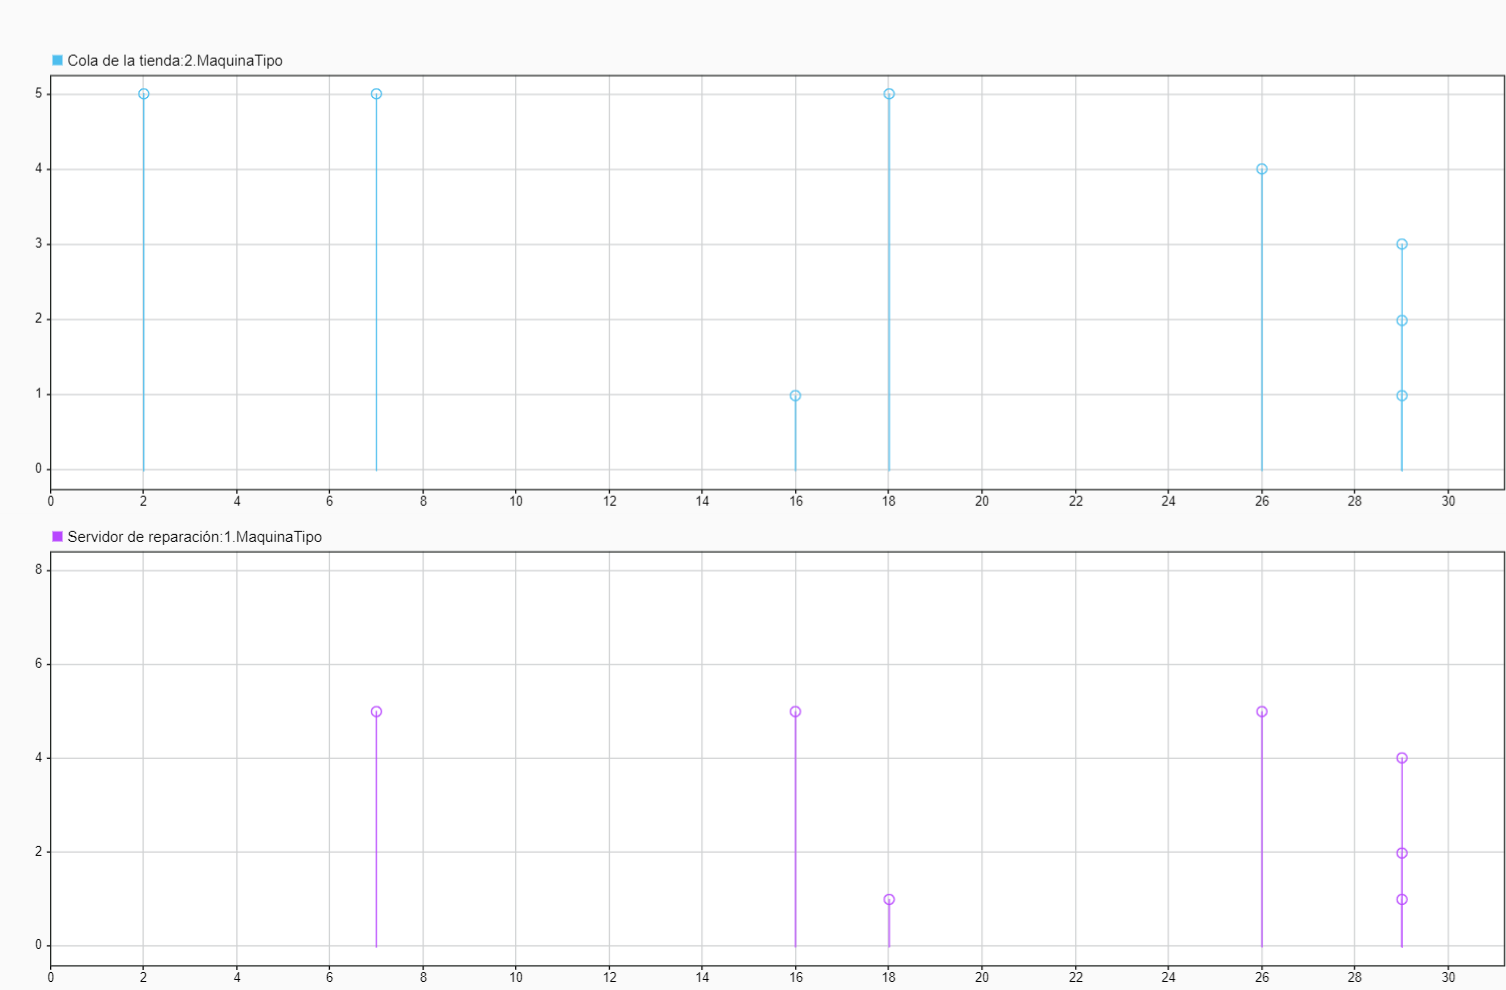

**Cálculo de la eficiencia del modelo 1 analíticamente con MATLAB:**

clear     % limpieza del espacio de trabajo
clc       % limpieza de línea de comando
close all % cerrar todas las figuras

#### Configuración usuario 

Se muestran los ajustes elejidos por el usuario aplicables a cualquier modelo de simulación discreta. 

Configuración del solver

solver = struct();
solver.type = "Variable-Step";
solver.name = "ode45";
solver.start = 0;
solver.stop = 30;   
solver.step = 1;

Nombre del modelo

model_name = "poisson";

sim_config, función que simula el modelo de nombre model_name para una configuración de solver almacenada en el struct solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

sim_data = sim_config(model_name, solver); % End of file definition

De sim_data se extrae la información de la simulación gracias a bloques output.

Obtenemos un data set con las señales del campo yout

signals = sim_data.yout;

Tiempo medio:

% Tiempo medio de reparación
t_medio_modelo1 = signals{2}.Values.Data;
t_medio_modelo1(end)

ans = 3.8571

Unidades reparadas:

m_reparadas = signals{1}.Values.Data;
% El último elemento, es el número de máquinas reparadas en el tiempo final
m_reparadas(end)

ans = 7

Con este modelo, obtenemos que en 30 unidades de tiempo, han sido **reparadas 7 máquinas**. Vamos a tener en cuenta estas cifras para comparar luego el otro modelo y ver cuál es mejor.

Por último, echamos un vistazo en sequence viewer a nuestro modelo.

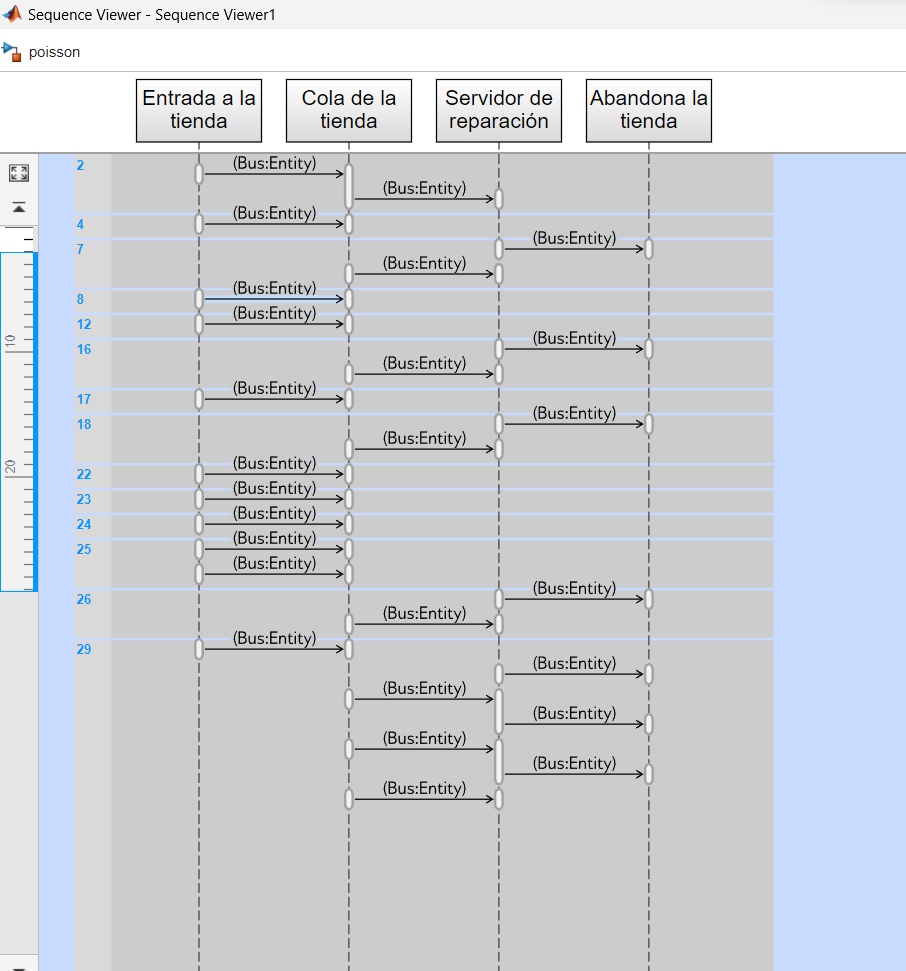

De la misma manera que hemos calculado, muestra que 7 máquinas abandonan la tienda y todo el proceso por el que pasa cada máquina desde que se genera, se mete en cola, va al servidor de reparación y sale de la tienda reparada. Además se ve que no todas las entidades están el mismo tiempo en el servidor, ya que cada una, dependiendo del tipo que sea, tiene un tiempo de reparación con media distinta en la distribución de Poisson.

### **MODELO 2**

El modelo elegido es el mismo que el anterior, con la diferencia de que habrá 5 servidores, para cada tipo de máquina. Un clasificador, leerá el tipo de máquina y la redirigirá a su servidor de reparación correspondiente:

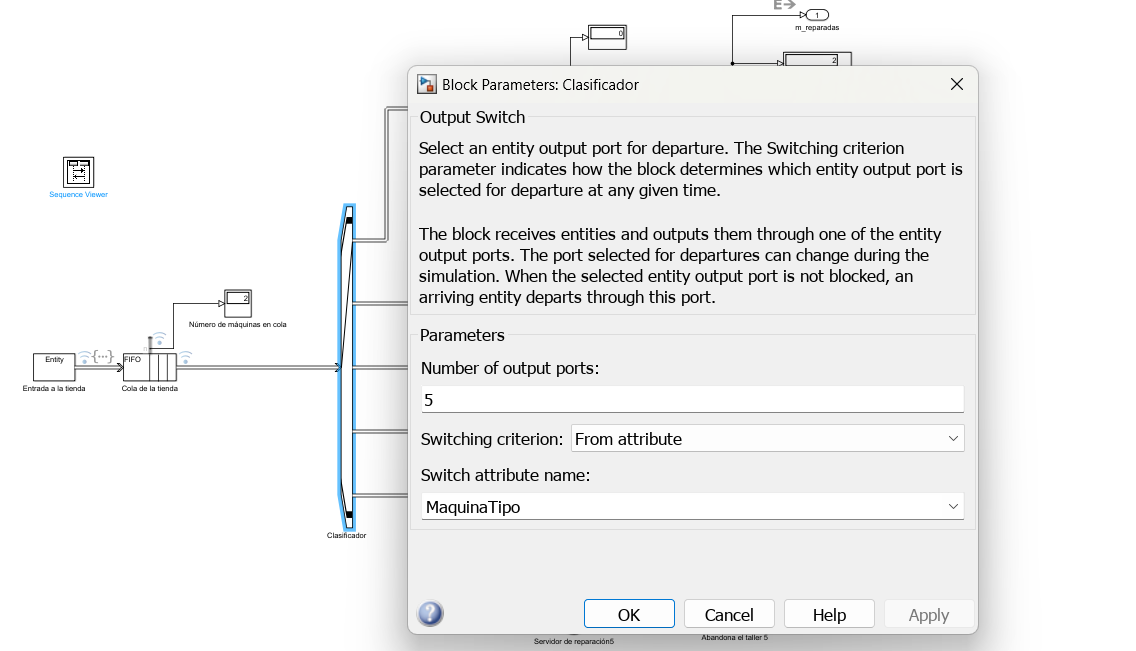

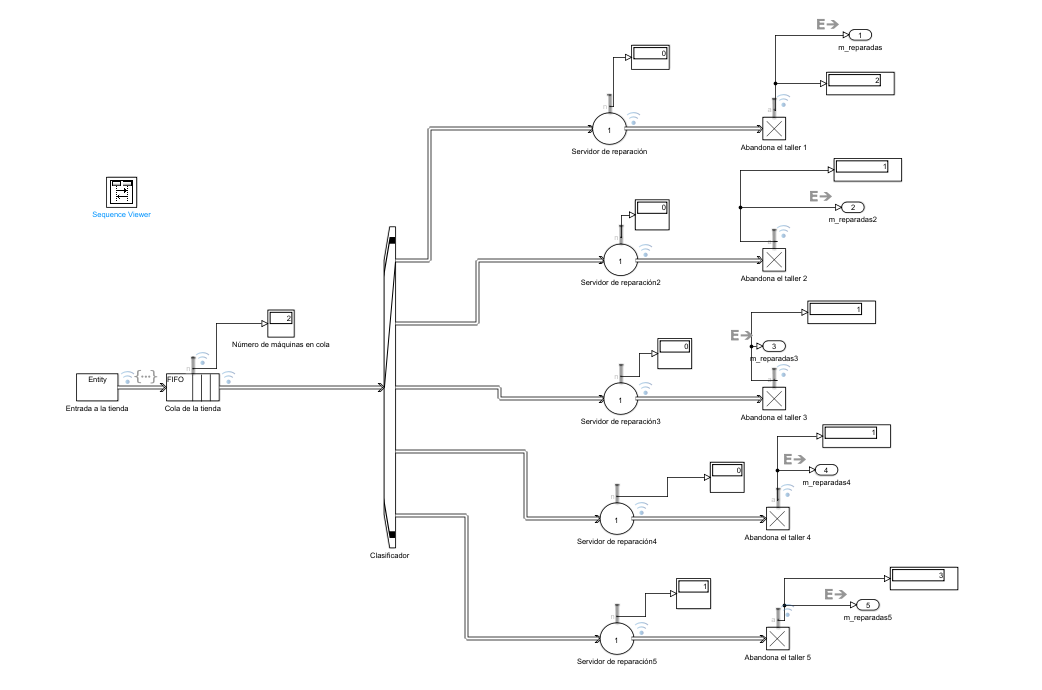

**Gráficas del modelo:**

Al igual que antes, se generan unas entidades, máquinas que van a una cola, donde se distingue de qué tipo son (1-5) y cada tipo es redirigido a un servidor. Por ejemplo, el servidor de reparación 5, que aparece en color naranja, solo contiene máquinas del tipo 5, la altura de los elementos naranjas es 5 en la gráfica.

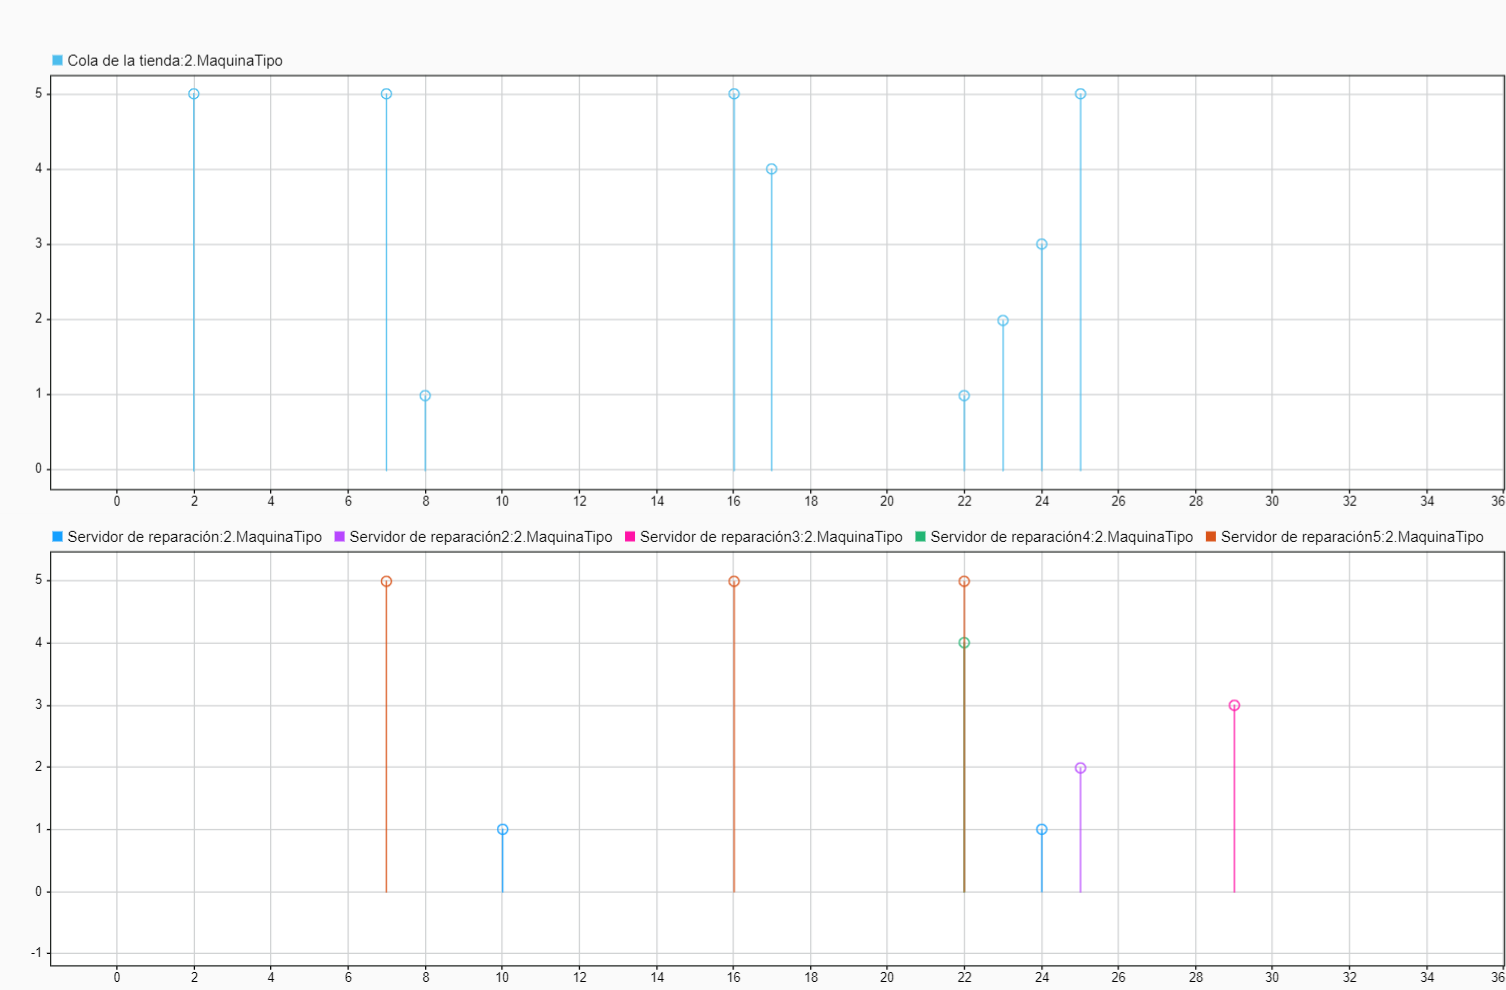

Si comparamos la gráfica de la cola con el modelo anterior, vemos que se aprovecha más la capacidad de la cola.

**Cálculo de la eficiencia del modelo 2 analíticamente con MATLAB:**

clear     % limpieza del espacio de trabajo
clc       % limpieza de línea de comando
close all % cerrar todas las figuras

#### Configuración usuario 

Se muestran los ajustes elejidos por el usuario aplicables a cualquier modelo de simulación discreta. 

Configuración del solver

solver = struct();
solver.type = "Variable-Step";
solver.name = "ode45";
solver.start = 0;
solver.stop = 30;   
solver.step = 1;

Nombre del modelo

model_name = "poisson2";

sim_config, función que simula el modelo de nombre model_name para una configuración de solver almacenada en el struct solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

sim_data = sim_config(model_name, solver); % End of file definition

De sim_data se extrae la información de la simulación gracias a bloques output.

Obtenemos un data set con las señales del campo yout

signals = sim_data.yout;

Tiempo medio:

% Tiempo medio de reparación
t_medio1_modelo2 = signals{6}.Values.Data;
t_medio2_modelo2 = signals{7}.Values.Data;
t_medio3_modelo2 = signals{8}.Values.Data;
t_medio4_modelo2 = signals{9}.Values.Data;
t_medio5_modelo2 = signals{10}.Values.Data;
t_medio1_modelo2(end)

ans = 2

t_medio2_modelo2(end)

ans = 2

t_medio3_modelo2(end)

ans = 5

t_medio4_modelo2(end)

ans = 5

t_medio5_modelo2(end)

ans = 6.6667

Unidades reparadas:

% Unidades reparadas
m_reparadas1 = signals{1}.Values.Data;
m_reparadas2 = signals{2}.Values.Data;
m_reparadas3 = signals{3}.Values.Data;
m_reparadas4 = signals{4}.Values.Data;
m_reparadas5 = signals{5}.Values.Data;

Veamos en total cuántas máquinas han sido reparadas:

sum = m_reparadas1(end) + m_reparadas2(end) + m_reparadas3(end) + m_reparadas4(end) + m_reparadas5(end)

sum = 8

Con este modelo, obtenemos que en 30 unidades de tiempo, han sido **reparadas 8 máquinas**. En comparación con el modelo anterior, hay una mejora de una máquina más reparada y se aprovecha mejor la capacidad de la cola por lo que es un poco más eficiente. También vemos que los tiempos medios son mejores en algunos servidores del modelo 2.

## Problema 2

Estamos estudiando la creación de un negocio de reparación de cascos de barcos de recreo. Lógicamente, hay muchos tipos de cascos, con diferentes tamaños y materiales, y se quiere probar la forma más eficiente de repararlas.

La primera forma de organizar la producción es reparar bajo pedido, esto es, se repara aquel casco que previamente se ha depositado en alguno de los concesionarios del puerto deportivo, y por tanto, se mezclarán en la reparación distintos tipos de barcos. Por ello, la llegada a la línea de reparación será una distribución de Poisson de media dos. Como son cascos distintos, sus tiempos de reparación son distintos (existen cuatro tipos de cascos a reparar). No sabemos qué tipo de barco puede llegar en cada momento. Los tiempos de reparación siguen una distribución de Poisson de media uno, dos, tres y cuatro respectivamente.

La segunda forma de organizar la reparación es más homogénea: existe una línea de reparación por cada tipo de casco, cada una de ellas con las mismas tasas de llegada y los mismos tiempos de reparación que la formulación anterior.

Con esta información, se desea saber qué tipo de línea de reparación es más eficiente en un periodo de tiempo dado y cuántos cascos salen reparados en cada una de las configuraciones al final del periodo. Incluya las gráficas que sean necesarias para poder comparar ambas configuraciones. En especial, se desea saber en todo momento los cascos que se encuentran en cola en cada una de las configuraciones. ¿Cuál sería el tiempo medio de reparación en cada una de las configuraciones?

Si necesita hacer suposiciones, indíquelas claramente siempre y cuando no simplifiquen el problema.

### Solución		

## Problema 3	

Estamos estudiando la creación de un negocio de reparación de motores de automóviles. Lógicamente, hay muchos tipos de motores, con diferentes cilindradas, combustibles y sofisticación, y se quiere probar la forma más eficiente de repararlos.

La primera forma de organizar la reparación es trabajar bajo demanda, esto es, se repara aquel motor que previamente se ha entregado en alguno de los concesionarios de la ciudad, y por tanto, se mezclarán en la reparación distintos tipos de motores. Por ello, la llegada a la línea de reparación será una distribución de Poisson de media dos. Como son motores distintos, sus tiempos de reparación son distintos (existen cuatro tipos de cascos a reparar). No sabemos qué tipo de motor puede llegar en cada momento. Los tiempos de reparación siguen una distribución de Poisson de media uno, dos, tres y cuatro respectivamente.

La segunda forma de organizar la reparación es más homogénea: existe una línea de reparación por cada tipo de motor, cada una de ellas con las mismas tasas de llegada y los mismos tiempos de reparación que la formulación anterior.

Con esta información, se desea saber qué tipo de línea de reparación es más eficiente en un periodo de tiempo dado y cuántos motores salen reparados en cada una de las configuraciones al final del periodo. Incluya las gráficas que sean necesarias para poder comparar ambas configuraciones. En especial, se desea saber en todo momento los tiempos medios de espera de los motores que se encuentran en cola en cada una de las configuraciones. ¿Cuál sería el tiempo medio de reparación en cada una de las configuraciones?

Si necesita hacer suposiciones, indíquelas claramente siempre y cuando no simplifiquen el problema.

### Solución

### ***Funciones disponibles para todas las secciones***

MATLAB permite utilizar la última sección de un livescript para definir funciones globales.

**Decorador de la función sim de MATLAB**

Esta función ejecuta la función sim, tras establecer los parámetros del solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

function sim_data = sim_config(model_name, solver)

Carga del modelo con load_system

load_system(model_name)
% open_system(model_name) will also open it

Configuración con set_param

% Set solver parameters
set_param(model_name, ...
    SolverType  = solver.type, ...
    SolverName  = solver.name, ...
    StartTime   = string(solver.start),...
    StopTime    = string(solver.stop), ...
    FixedStep   = string(solver.step) ...
    )
% More model parameters can be retrieved with:
% model_data = get_param(model_name, "ObjectParameters")
% Access blocks params with "model_name/block_name"

Simulación del modelo con sim

sim_data = sim(model_name);
% SimulationMode="normal" by default
end

Se utiliza el bloque Out1 para cada señal.